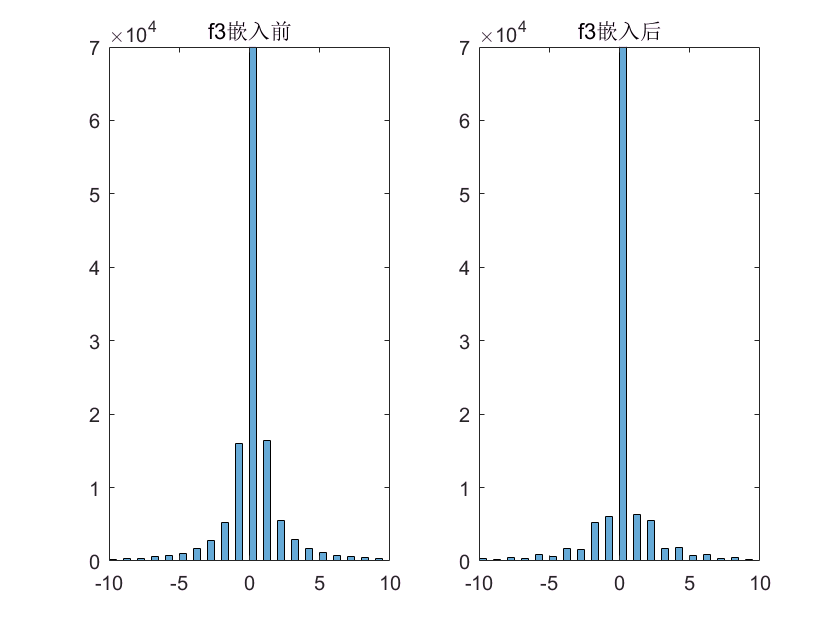

clear;
COVER='cover.jpg';     % 原图
STEGO='output.jpg';     % 隐藏信息图
MSG='information.txt';          % 信息
RES='get.txt';          % 还原信息


    fp=fopen(MSG,'r');
    [msg,len]=fread(fp,'ubit1');
    msg=msg';
%     计时、计数
    tic;

    jobj=jpeg_read(COVER);
    DCT=jobj.coef_arrays{1};
    DCT2=DCT;

    AC=numel(DCT)-numel(DCT(1:8:end,1:8:end));

    if(length(msg)>AC)
        error('ERROR(too long message)');
    end
    
    pos=true(size(DCT));
    pos(1:8:end,1:8:end)=false;
    pos=find(pos);
    change=0;
    j=1;
    for i=1:len
        while(1)
		%     寻找可以嵌入的AC系数
            if((DCT(pos(j))==1 && msg(i)==0) || (DCT(pos(j))==-1 && msg(i)==0) || (DCT(pos(j))==0))
                if(DCT(pos(j))~=0)
                    change=change+1;
                end
                DCT2(pos(j))=0;
                j=j+1;           
                if(j>=AC)
                    break;
                end
            else
                break;
            end
        end
%         嵌入第pos(j)个AC系数
        if(j>=AC)
            break;
        end
        if(DCT(pos(j))>0 && msg(i)~=mod(DCT2(pos(j)),2))
            change=change+1;
            DCT2(pos(j))=DCT2(pos(j))-1;
        elseif(DCT(pos(j))<0 && msg(i)~=mod(DCT2(pos(j)),2))
            change=change+1;
            DCT2(pos(j))=DCT2(pos(j))+1;
        end
        j=j+1;
        if(j>=AC)
            break;
        end
    end
%     直方图
     figure();
     subplot(121);histogram(DCT);axis([-10,10,0,7*1e4]);title("f3嵌入前");
     subplot(122);histogram(DCT2);axis([-10,10,0,7*1e4]);title("f3嵌入后");

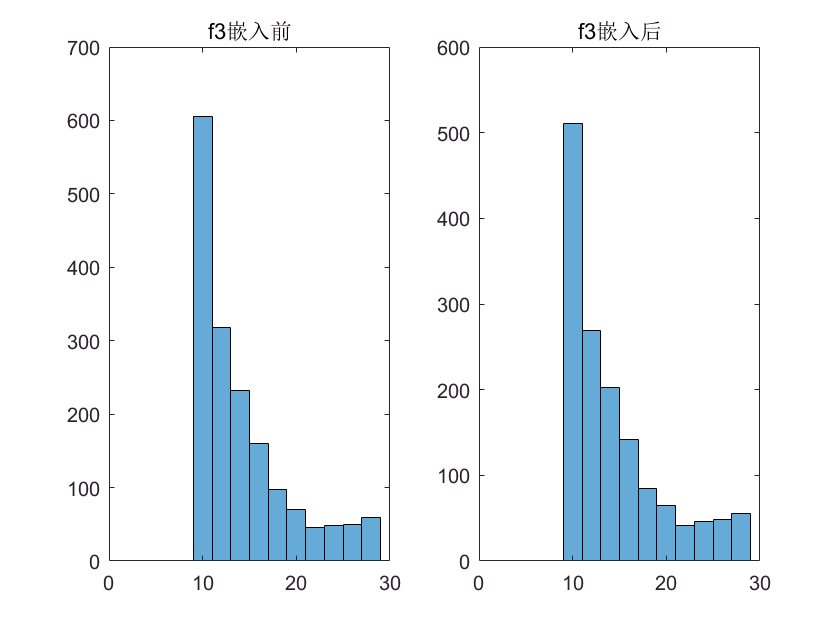

%     值对现象
     figure();
     subplot(121);histogram(DCT,(10:1:30));title("f3嵌入前");
     subplot(122);histogram(DCT2,(10:1:30));title("f3嵌入后");

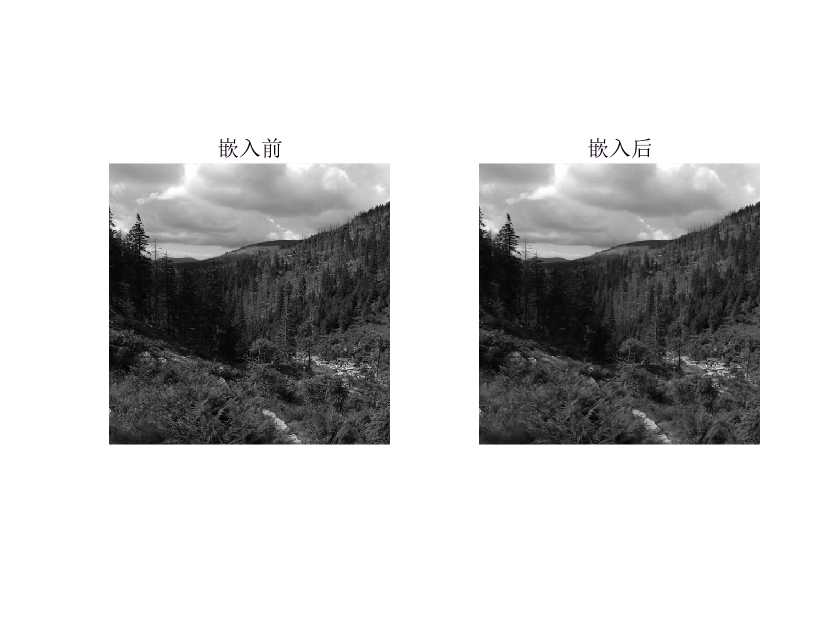

    try
        jobj.coef_arrays{1}=DCT2;
        jobj.optimize_coding=1;
        jpeg_write(jobj,STEGO);
    catch
        error('ERROR(problem with saving the stego image)')
    end
%     图片对比
     figure();
     subplot(121);imshow(COVER);title("嵌入前");
     subplot(122);imshow(STEGO);title("嵌入后");

    T=toc;
    fprintf('嵌入时间:%4f秒\n',T);

嵌入时间:59.371587秒


    fprintf('嵌入信息:%d比特\n',i);

嵌入信息:37354比特


    fprintf('修改的AC系数个数:%d个\n',change);

修改的AC系数个数:36807个


    fclose(fp);

clear;
COVER='cover.jpg';     % 原图
STEGO='output.jpg';     % 隐藏信息图
MSG='information.txt';          % 信息
RES='get.txt';          % 还原信息
len=10086;

    fp=fopen(RES,'w');
    jobj=jpeg_read(STEGO);
    DCT=jobj.coef_arrays{1};


    pos=true(size(DCT));
    pos(1:8:end,1:8:end)=false;
    pos=find(pos);
    j=1;
    for i=1:len
        while(DCT(pos(j))==0)
            j=j+1;
        end

            fwrite(fp,mod(DCT(pos(j)),2),'ubit1');

        j=j+1;
    end
    fclose(fp);